# Team 3: Movable Hexapod Robot Simulation Visualization

#### Gary Encinas, Justin Fossum, Jason Munger, and Mithulesh Ramkumar

## Building The Model

This code was derived and adjusted from our group script called "Hexapod_Robot_Full_Model.mlx" in which we built the full rigid body model of the robot with STL meshes for the first time.

### Environment Setup

First, we should remove items from workspace, freeing up system memory, and clear current command window.

clf('reset'); %Clear current figure window
clear; % Remove items from workspace, freeing up system memory
clc; % Clear current command window

Next we should set the script control variables and import any variables that we might need.

climbing_slope = false; % Set to control if the robot is walking up a slope (true or false)
slope_type = 'xy'; % Set to control which slope the robot will climb ('x' or 'xy')
make_video = true; % Set to output videos or not (true or false)

error_id = 'SimViz:BadSlope';
msg = 'Unable to match slope input case.';
base_exception = MException(error_id,msg);

if climbing_slope
    if strcmpi(slope_type, 'x')
        load(".\From Jason\Rx 35 Ry 0 Variables\Xworld.mat");
        load(".\From Jason\Rx 35 Ry 0 Variables\Poses.mat");
        load(".\From Jason\Rx 35 Ry 0 Variables\Joint_Angles.mat");
    elseif strcmpi(slope_type, 'xy')
        load(".\From Jason\Rx 23.5 Ry 23.5 Variables\Xworld.mat");
        load(".\From Jason\Rx 23.5 Ry 23.5 Variables\Poses.mat");
        load(".\From Jason\Rx 23.5 Ry 23.5 Variables\Joint_Angles.mat");
    else
        throw(base_exception);
    end
else
    load(".\From Jason\Rx 0 Ry 0 Variables\Xworld.mat");
    load(".\From Jason\Rx 0 Ry 0 Variables\Poses.mat");
    load(".\From Jason\Rx 0 Ry 0 Variables\Joint_Angles.mat");
end

path = zeros(3,size(Xworld,2));

### Building the Rigid Tree Model

When building this model, the leg length visuals and collision meshes are reused, so rather than the full string path every time, we have listed them all as variables in the beginning. Keeping true with that fashion, the DH parameters are only changed by a ratio of $\frac{\pi }{3}$ each new leg so there is a count variable that can be called to index the leg creations.

body_mesh = "..\Robot CAD\STL\Body_Link.STL";
link1_vmesh = "..\Robot CAD\STL\Link_One_L2Out.STL";
link2_vmesh = "..\Robot CAD\STL\Link_Two_640_L3Out.STL";
if climbing_slope
    link3_vmesh = "..\Robot CAD\STL\Link_Three_960_EEOut_MovedFoot_500.STL";
else
    link3_vmesh = "..\Robot CAD\STL\Link_Three_960_EEOut_MovedFoot_700.STL";
end
link1_cmesh1 = "..\Robot CAD\STL\Collision\Link_One_Part1.STL";
link1_cmesh2 = "..\Robot CAD\STL\Collision\Link_One_Part2.STL";
link1_cmesh3 = "..\Robot CAD\STL\Collision\Link_One_Part3.STL";

link2_cmesh1 = "..\Robot CAD\STL\Collision\Link_Two_Part1.STL";
link2_cmesh2 = "..\Robot CAD\STL\Collision\Link_Two_Part2.STL";
link2_cmesh3 = "..\Robot CAD\STL\Collision\Link_Two_Part3.STL";
link2_cmesh4 = "..\Robot CAD\STL\Collision\Link_Two_Part4.STL";
link2_cmesh5 = "..\Robot CAD\STL\Collision\Link_Two_Part5.STL";

link3_cmesh1 = "..\Robot CAD\STL\Collision\Link_Three_Part1.STL";
link3_cmesh2 = "..\Robot CAD\STL\Collision\Link_Three_Part2.STL";
link3_cmesh3 = "..\Robot CAD\STL\Collision\Link_Three_Part3.STL";
link3_cmesh4 = "..\Robot CAD\STL\Collision\Link_Three_Part4.STL";
link3_cmesh5 = "..\Robot CAD\STL\Collision\Link_Three_Part5.STL";

count = 1; % Counting variable for itterating through the legs with the order being 2, 1, 3, 5, 6, 4 for leg names.

a = [0.625 0 0.640 0.960]; % Link lengths as a 1:1.5 leg ratio.
alpha = [0 pi/2 0 -pi/2];
d = [0 0 0 0];
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];

%Building The Robot by creating a rigid body tree
full_robot = robotics.RigidBodyTree; %Sets rigid body tree to be called robot for callback use

% Define the bodies and their joints
leg_1 = robotics.RigidBody('leg_1'); %Create Leg 1 Origin of the robot.
leg_2 = robotics.RigidBody('leg_2'); %Create Leg 2 Origin of the robot.
leg_3 = robotics.RigidBody('leg_3'); %Create Leg 3 Origin of the robot.
leg_4 = robotics.RigidBody('leg_4'); %Create Leg 4 Origin of the robot.
leg_5 = robotics.RigidBody('leg_5'); %Create Leg 5 Origin of the robot.
leg_6 = robotics.RigidBody('leg_6'); %Create Leg 6 Origin of the robot.

leg1_jnt1 = robotics.Joint('leg1_jnt1','fixed'); %Create a fixed joint.
leg2_jnt1 = robotics.Joint('leg2_jnt1','fixed'); %Create a fixed joint.
leg3_jnt1 = robotics.Joint('leg3_jnt1','fixed'); %Create a fixed joint.
leg4_jnt1 = robotics.Joint('leg4_jnt1','fixed'); %Create a fixed joint.
leg5_jnt1 = robotics.Joint('leg5_jnt1','fixed'); %Create a fixed joint.
leg6_jnt1 = robotics.Joint('leg6_jnt1','fixed'); %Create a fixed joint.

leg1_link1 = robotics.RigidBody('leg1_link1'); %Create Link 1 of the leg 1.
leg2_link1 = robotics.RigidBody('leg2_link1'); %Create Link 1 of the leg 2.
leg3_link1 = robotics.RigidBody('leg3_link1'); %Create Link 1 of the leg 3.
leg4_link1 = robotics.RigidBody('leg4_link1'); %Create Link 1 of the leg 4.
leg5_link1 = robotics.RigidBody('leg5_link1'); %Create Link 1 of the leg 5.
leg6_link1 = robotics.RigidBody('leg6_link1'); %Create Link 1 of the leg 6.

leg1_jnt2 = robotics.Joint('leg1_jnt2','revolute'); %Create a revolute joint.
leg2_jnt2 = robotics.Joint('leg2_jnt2','revolute'); %Create a revolute joint.
leg3_jnt2 = robotics.Joint('leg3_jnt2','revolute'); %Create a revolute joint.
leg4_jnt2 = robotics.Joint('leg4_jnt2','revolute'); %Create a revolute joint.
leg5_jnt2 = robotics.Joint('leg5_jnt2','revolute'); %Create a revolute joint.
leg6_jnt2 = robotics.Joint('leg6_jnt2','revolute'); %Create a revolute joint.

leg1_link2 = robotics.RigidBody('leg1_link2'); %Create Link 2 of the leg 1.
leg2_link2 = robotics.RigidBody('leg2_link2'); %Create Link 2 of the leg 2.
leg3_link2 = robotics.RigidBody('leg3_link2'); %Create Link 2 of the leg 3.
leg4_link2 = robotics.RigidBody('leg4_link2'); %Create Link 2 of the leg 4.
leg5_link2 = robotics.RigidBody('leg5_link2'); %Create Link 2 of the leg 5.
leg6_link2 = robotics.RigidBody('leg6_link2'); %Create Link 2 of the leg 6.

leg1_jnt3 = robotics.Joint('leg1_jnt3','revolute'); %Create a revolute joint.
leg2_jnt3 = robotics.Joint('leg2_jnt3','revolute'); %Create a revolute joint.
leg3_jnt3 = robotics.Joint('leg3_jnt3','revolute'); %Create a revolute joint.
leg4_jnt3 = robotics.Joint('leg4_jnt3','revolute'); %Create a revolute joint.
leg5_jnt3 = robotics.Joint('leg5_jnt3','revolute'); %Create a revolute joint.
leg6_jnt3 = robotics.Joint('leg6_jnt3','revolute'); %Create a revolute joint.

leg1_link3 = robotics.RigidBody('leg1_link3'); %Create Link 3 of the leg 1.
leg2_link3 = robotics.RigidBody('leg2_link3'); %Create Link 3 of the leg 2.
leg3_link3 = robotics.RigidBody('leg3_link3'); %Create Link 3 of the leg 3.
leg4_link3 = robotics.RigidBody('leg4_link3'); %Create Link 3 of the leg 4.
leg5_link3 = robotics.RigidBody('leg5_link3'); %Create Link 3 of the leg 5.
leg6_link3 = robotics.RigidBody('leg6_link3'); %Create Link 3 of the leg 6.

leg1_jnt4 = robotics.Joint('leg1_jnt4','revolute'); %Create a revolute joint.
leg2_jnt4 = robotics.Joint('leg2_jnt4','revolute'); %Create a revolute joint.
leg3_jnt4 = robotics.Joint('leg3_jnt4','revolute'); %Create a revolute joint.
leg4_jnt4 = robotics.Joint('leg4_jnt4','revolute'); %Create a revolute joint.
leg5_jnt4 = robotics.Joint('leg5_jnt4','revolute'); %Create a revolute joint.
leg6_jnt4 = robotics.Joint('leg6_jnt4','revolute'); %Create a revolute joint.

% Specify the body-to-body transformation using DH parameters
setFixedTransform(leg2_jnt1,DHparams(1,:),'dh');
count = count + 1; % Index the count variable for the next leg origin.
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];
setFixedTransform(leg1_jnt1,DHparams(1,:),'dh');
count = count + 1; % Index the count variable for the next leg origin.
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];
setFixedTransform(leg3_jnt1,DHparams(1,:),'dh');
count = count + 1; % Index the count variable for the next leg origin.
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];
setFixedTransform(leg5_jnt1,DHparams(1,:),'dh');
count = count + 1; % Index the count variable for the next leg origin.
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];
setFixedTransform(leg6_jnt1,DHparams(1,:),'dh');
count = count + 1; % Index the count variable for the next leg origin.
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];
setFixedTransform(leg4_jnt1,DHparams(1,:),'dh');
count = count + 1; % Index the count variable for the next leg origin.
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];

setFixedTransform(leg1_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg1_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg1_jnt4,DHparams(4,:),'dh');

setFixedTransform(leg2_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg2_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg2_jnt4,DHparams(4,:),'dh');

setFixedTransform(leg3_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg3_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg3_jnt4,DHparams(4,:),'dh');

setFixedTransform(leg4_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg4_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg4_jnt4,DHparams(4,:),'dh');

setFixedTransform(leg5_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg5_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg5_jnt4,DHparams(4,:),'dh');

setFixedTransform(leg6_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg6_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg6_jnt4,DHparams(4,:),'dh');

% Specify the body joints
leg_1.Joint = leg1_jnt1;
leg_2.Joint = leg2_jnt1;
leg_3.Joint = leg3_jnt1;
leg_4.Joint = leg4_jnt1;
leg_5.Joint = leg5_jnt1;
leg_6.Joint = leg6_jnt1;

leg1_link1.Joint = leg1_jnt2;
leg1_link2.Joint = leg1_jnt3;
leg1_link3.Joint = leg1_jnt4;

leg2_link1.Joint = leg2_jnt2;
leg2_link2.Joint = leg2_jnt3;
leg2_link3.Joint = leg2_jnt4;

leg3_link1.Joint = leg3_jnt2;
leg3_link2.Joint = leg3_jnt3;
leg3_link3.Joint = leg3_jnt4;

leg4_link1.Joint = leg4_jnt2;
leg4_link2.Joint = leg4_jnt3;
leg4_link3.Joint = leg4_jnt4;

leg5_link1.Joint = leg5_jnt2;
leg5_link2.Joint = leg5_jnt3;
leg5_link3.Joint = leg5_jnt4;

leg6_link1.Joint = leg6_jnt2;
leg6_link2.Joint = leg6_jnt3;
leg6_link3.Joint = leg6_jnt4;

% Add the STL visual to the body
addVisual(leg_2, "Mesh", body_mesh);

% Add the STL visual to the first links
addVisual(leg1_link1, "Mesh", link1_vmesh);
addVisual(leg2_link1, "Mesh", link1_vmesh);
addVisual(leg3_link1, "Mesh", link1_vmesh);
addVisual(leg4_link1, "Mesh", link1_vmesh);
addVisual(leg5_link1, "Mesh", link1_vmesh);
addVisual(leg6_link1, "Mesh", link1_vmesh);

% Add the STL visual to the second links
addVisual(leg1_link2, "Mesh", link2_vmesh);
addVisual(leg2_link2, "Mesh", link2_vmesh);
addVisual(leg3_link2, "Mesh", link2_vmesh);
addVisual(leg4_link2, "Mesh", link2_vmesh);
addVisual(leg5_link2, "Mesh", link2_vmesh);
addVisual(leg6_link2, "Mesh", link2_vmesh);

% Add the STL visual to the third links
addVisual(leg1_link3, "Mesh", link3_vmesh);
addVisual(leg2_link3, "Mesh", link3_vmesh);
addVisual(leg3_link3, "Mesh", link3_vmesh);
addVisual(leg4_link3, "Mesh", link3_vmesh);
addVisual(leg5_link3, "Mesh", link3_vmesh);
addVisual(leg6_link3, "Mesh", link3_vmesh);

% Attach the first Leg
addBody(full_robot,leg_1,'base')
addBody(full_robot,leg1_link1,'leg_1');
addBody(full_robot,leg1_link2,'leg1_link1');
addBody(full_robot,leg1_link3,'leg1_link2');

% Attach the second Leg
addBody(full_robot,leg_2,'base')
addBody(full_robot,leg2_link1,'leg_2');
addBody(full_robot,leg2_link2,'leg2_link1');
addBody(full_robot,leg2_link3,'leg2_link2');

% Attach the third Leg
addBody(full_robot,leg_3,'base')
addBody(full_robot,leg3_link1,'leg_3');
addBody(full_robot,leg3_link2,'leg3_link1');
addBody(full_robot,leg3_link3,'leg3_link2');

% Attach the fourth Leg
addBody(full_robot,leg_4,'base')
addBody(full_robot,leg4_link1,'leg_4');
addBody(full_robot,leg4_link2,'leg4_link1');
addBody(full_robot,leg4_link3,'leg4_link2');

% Attach the fifth Leg
addBody(full_robot,leg_5,'base')
addBody(full_robot,leg5_link1,'leg_5');
addBody(full_robot,leg5_link2,'leg5_link1');
addBody(full_robot,leg5_link3,'leg5_link2');

% Attach the sixth Leg
addBody(full_robot,leg_6,'base')
addBody(full_robot,leg6_link1,'leg_6');
addBody(full_robot,leg6_link2,'leg6_link1');
addBody(full_robot,leg6_link3,'leg6_link2');

full_robot.DataFormat = 'row';
config = homeConfiguration(full_robot);

joint_1_co_ord = [1,1,1,1,1,1;  1,4,7,10,13,16];
joint_2_co_ord = [1,1,1,1,1,1;  2,5,8,11,14,17];
joint_3_co_ord = [1,1,1,1,1,1;  3,6,9,12,15,18];

% All of joint 1
config(sub2ind(size(config),joint_1_co_ord(1,:),joint_1_co_ord(2,:))) = 0;
% All of joint 2
config(sub2ind(size(config),joint_2_co_ord(1,:),joint_2_co_ord(2,:))) = deg2rad(32.391);
% All of joint 3
config(sub2ind(size(config),joint_3_co_ord(1,:),joint_3_co_ord(2,:))) = deg2rad(-93.789);

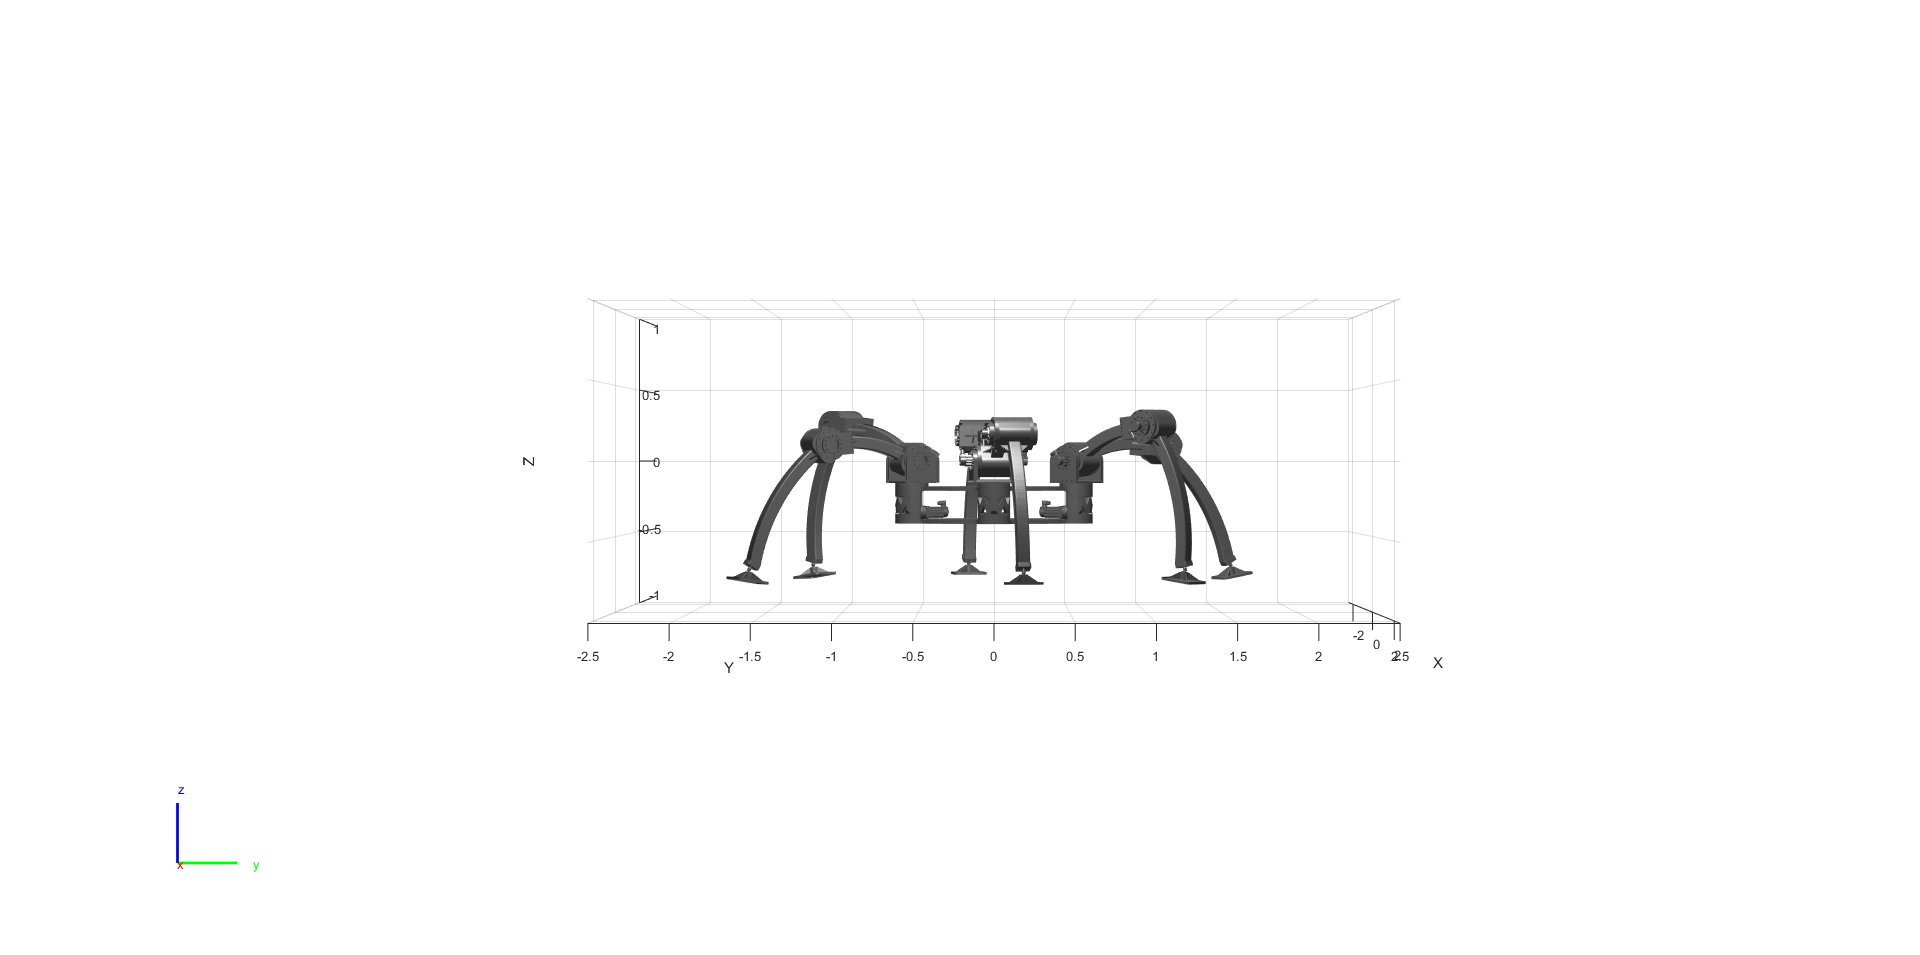

figure("WindowState","maximized");
% set(gca,'Xdir','reverse','Ydir','reverse')
full_robot_moved = rigidBodyTree;
rb = rigidBody('newBaseForFull_Robot');
if climbing_slope
    if strcmpi(slope_type, 'x')
        rot_x = [1, 0, 0, 0;
         0, cos(deg2rad(35)), -sin(deg2rad(35)), 0;
         0, sin(deg2rad(35)), cos(deg2rad(35)), 0;
         0, 0, 0, 1]; % Rotation about the X axis
        rotation = rot_x;
    elseif strcmpi(slope_type, 'xy')
        rot_x = [1, 0, 0, 0;
         0, cos(deg2rad(23.5)), -sin(deg2rad(23.5)), 0;
         0, sin(deg2rad(23.5)), cos(deg2rad(23.5)), 0;
         0, 0, 0, 1]; % Rotation about the X axis
        rot_y = [cos(deg2rad(23.5)), 0, sin(deg2rad(23.5)), 0;
         0, 1, 0, 0;
         -sin(deg2rad(23.5)), 0, cos(deg2rad(23.5)), 0;
         0, 0, 0, 1]; % Rotation about the Y axis
        rotation = rot_x*rot_y;
    else
        throw(base_exception);
    end
    
    rb.Joint.setFixedTransform(rotation*make_transform(Poses, Xworld, 1));
    point = rotation*make_transform(Poses, Xworld, 1);
    path(:,1) = point(1:3,4);
else
    rb.Joint.setFixedTransform(make_transform(Poses, Xworld, 1));
    point = make_transform(Poses, Xworld, 1);
    path(:,1) = point(1:3,4);
end
full_robot_moved.addBody(rb, 'base');
full_robot_moved.addSubtree('newBaseForFull_Robot', full_robot);
full_robot_moved.DataFormat = 'row';

config = current_config(Joint_Angles, 1);

show(full_robot,config,"Frames","off","PreservePlot",false,"FastUpdate",true);
view(2); % Top view of the robot
xlim([-2.5 2.5])
ylim([-2.5 2.5])
zlim([-1, 1])
drawnow;
if make_video
    H(1) = getframe(gcf); % Creates frame of each incremental movement from top view
end

view(180,0); % Front view of robot
drawnow;
if make_video
    I(1) = getframe(gcf); % Creates frame of each incremental movement from front view
end

view(90,0); % Side view of the robot

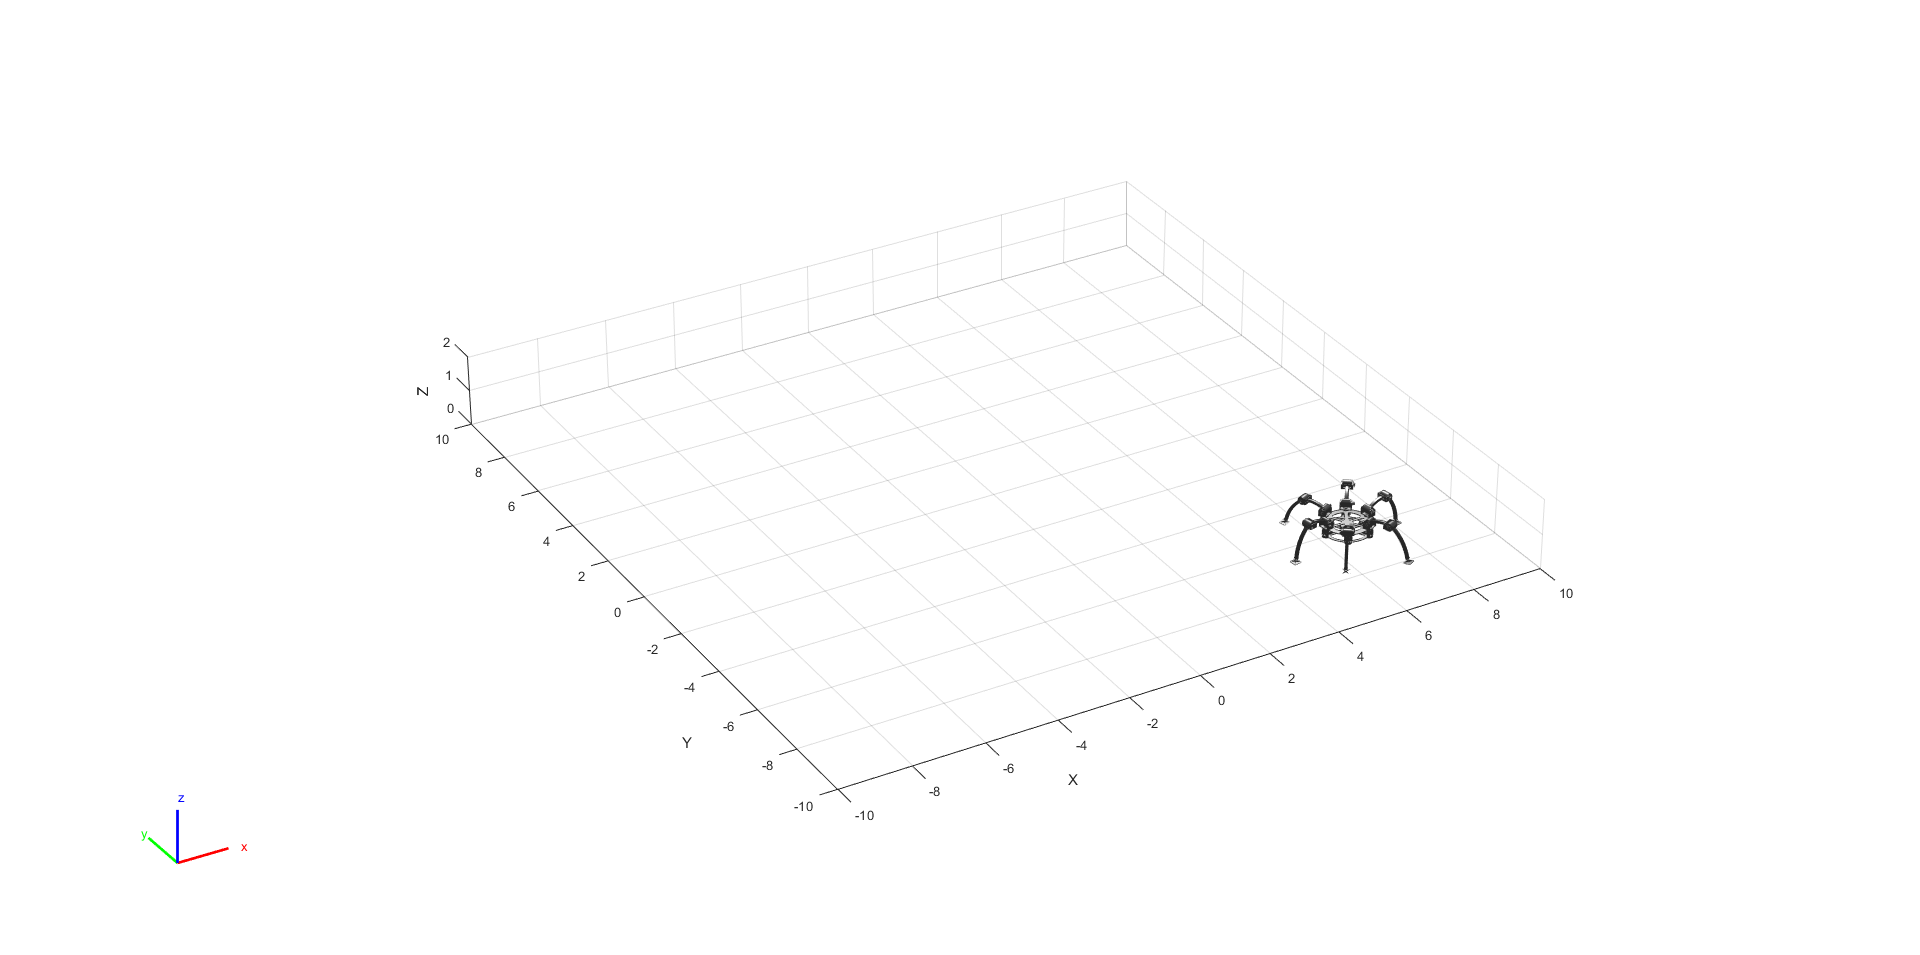

drawnow;
if make_video
    J(1) = getframe(gcf); % Creates frame of each incremental movement from side view
end

show(full_robot_moved,config,"Frames","off","PreservePlot",false,"FastUpdate",true);
if climbing_slope
        xlim([-10 10])
        ylim([-10 10])
        view(-30,30); %view(60,25);
        v1 = [-10 -10; 10 -10; 10 10; -10 10];
        f1 = [1 2 3 4];
        ground = patch('Faces',f1,'Vertices',v1,'FaceColor','red','FaceAlpha',.3);
        if strcmpi(slope_type, 'x')
            rotate(ground,[1 0 0],35);
            zlim([-5, 5.5])
        elseif strcmpi(slope_type, 'xy')
            rotate(ground,[1 0 0],23.5);
            rotate(ground,[0 1 0],23.5);
            zlim([-6.5, 5.5])
        else
            throw(base_exception);
        end
        hold on
        plot3(path(1,1),path(2,1),path(3,1),'-k')
    else
        xlim([-10 10])
        ylim([-10 10])
        zlim([0, 2])
        view(-30,30); %view(120,45);
        hold on
        plot3(path(1,1),path(2,1),path(3,1),'-k')
end
drawnow;

if make_video
    G(1) = getframe(gcf); % Creates frame of each incremental movement
end
tic
for iter=2:size(Xworld,2)
    hold off
    removeBody(full_robot_moved, 'newBaseForFull_Robot');
    if climbing_slope
        if strcmpi(slope_type, 'x')
            rot_x = [1, 0, 0, 0;
             0, cos(deg2rad(35)), -sin(deg2rad(35)), 0;
             0, sin(deg2rad(35)), cos(deg2rad(35)), 0;
             0, 0, 0, 1]; % Rotation about the X axis
            rotation = rot_x;
        elseif strcmpi(slope_type, 'xy')
            rot_x = [1, 0, 0, 0;
             0, cos(deg2rad(23.5)), -sin(deg2rad(23.5)), 0;
             0, sin(deg2rad(23.5)), cos(deg2rad(23.5)), 0;
             0, 0, 0, 1]; % Rotation about the X axis
            rot_y = [cos(deg2rad(23.5)), 0, sin(deg2rad(23.5)), 0;
             0, 1, 0, 0;
             -sin(deg2rad(23.5)), 0, cos(deg2rad(23.5)), 0;
             0, 0, 0, 1]; % Rotation about the Y axis
            rotation = rot_x*rot_y;
        else
            throw(base_exception);
        end
        
        rb.Joint.setFixedTransform(rotation*make_transform(Poses, Xworld, iter));
        point = rotation*make_transform(Poses, Xworld, iter);
        path(:,iter) = point(1:3,4);
    else
        rb.Joint.setFixedTransform(make_transform(Poses, Xworld, iter));
        point = make_transform(Poses, Xworld, iter);
        path(:,iter) = point(1:3,4);
    end
    full_robot_moved.addBody(rb, 'base');
    full_robot_moved.addSubtree('newBaseForFull_Robot', full_robot);
    
    config = current_config(Joint_Angles, iter);
    
    show(full_robot,config,"Frames","off","PreservePlot",false,"FastUpdate",true);
    view(2); % Top view of the robot
    xlim([-2.5 2.5])
    ylim([-2.5 2.5])
    zlim([-1, 1])
    drawnow;
    if make_video
        H(iter) = getframe(gcf); % Creates frame of each incremental movement from top view
    end

    view(180,0); % Front view of robot
    drawnow;
    if make_video
        I(iter) = getframe(gcf); % Creates frame of each incremental movement from front view
    end

    view(90,0); % Side view of the robot
    drawnow;
    if make_video
        J(iter) = getframe(gcf); % Creates frame of each incremental movement from side view
    end

    show(full_robot_moved,config,"Frames","off","PreservePlot",false,"FastUpdate",true);
    % set(gca,'Xdir','reverse','Ydir','reverse')
    % zoom(gca,'reset');
    if climbing_slope
        xlim([-10 10])
        ylim([-10 10])
        view(-30,30); %view(60,25);
        v1 = [-10 -10; 10 -10; 10 10; -10 10];
        f1 = [1 2 3 4];
        ground = patch('Faces',f1,'Vertices',v1,'FaceColor','red','FaceAlpha',.3);
        if strcmpi(slope_type, 'x')
            rotate(ground,[1 0 0],35);
            zlim([-5, 5.5])
        elseif strcmpi(slope_type, 'xy')
            rotate(ground,[1 0 0],23.5);
            rotate(ground,[0 1 0],23.5);
            zlim([-6.5, 5.5])
        else
            throw(base_exception);
        end
        hold on
        plot3(path(1,1:iter),path(2,1:iter),path(3,1:iter),'-k')
    else
        xlim([-10 10])
        ylim([-10 10])
        zlim([0, 2])
        view(-30,30); %view(120,45);
        hold on
        plot3(path(1,1:iter),path(2,1:iter),path(3,1:iter),'-k')
    end
    drawnow;

    if make_video
        G(iter) = getframe(gcf); % Creates frame of each incremental movement
    end
end

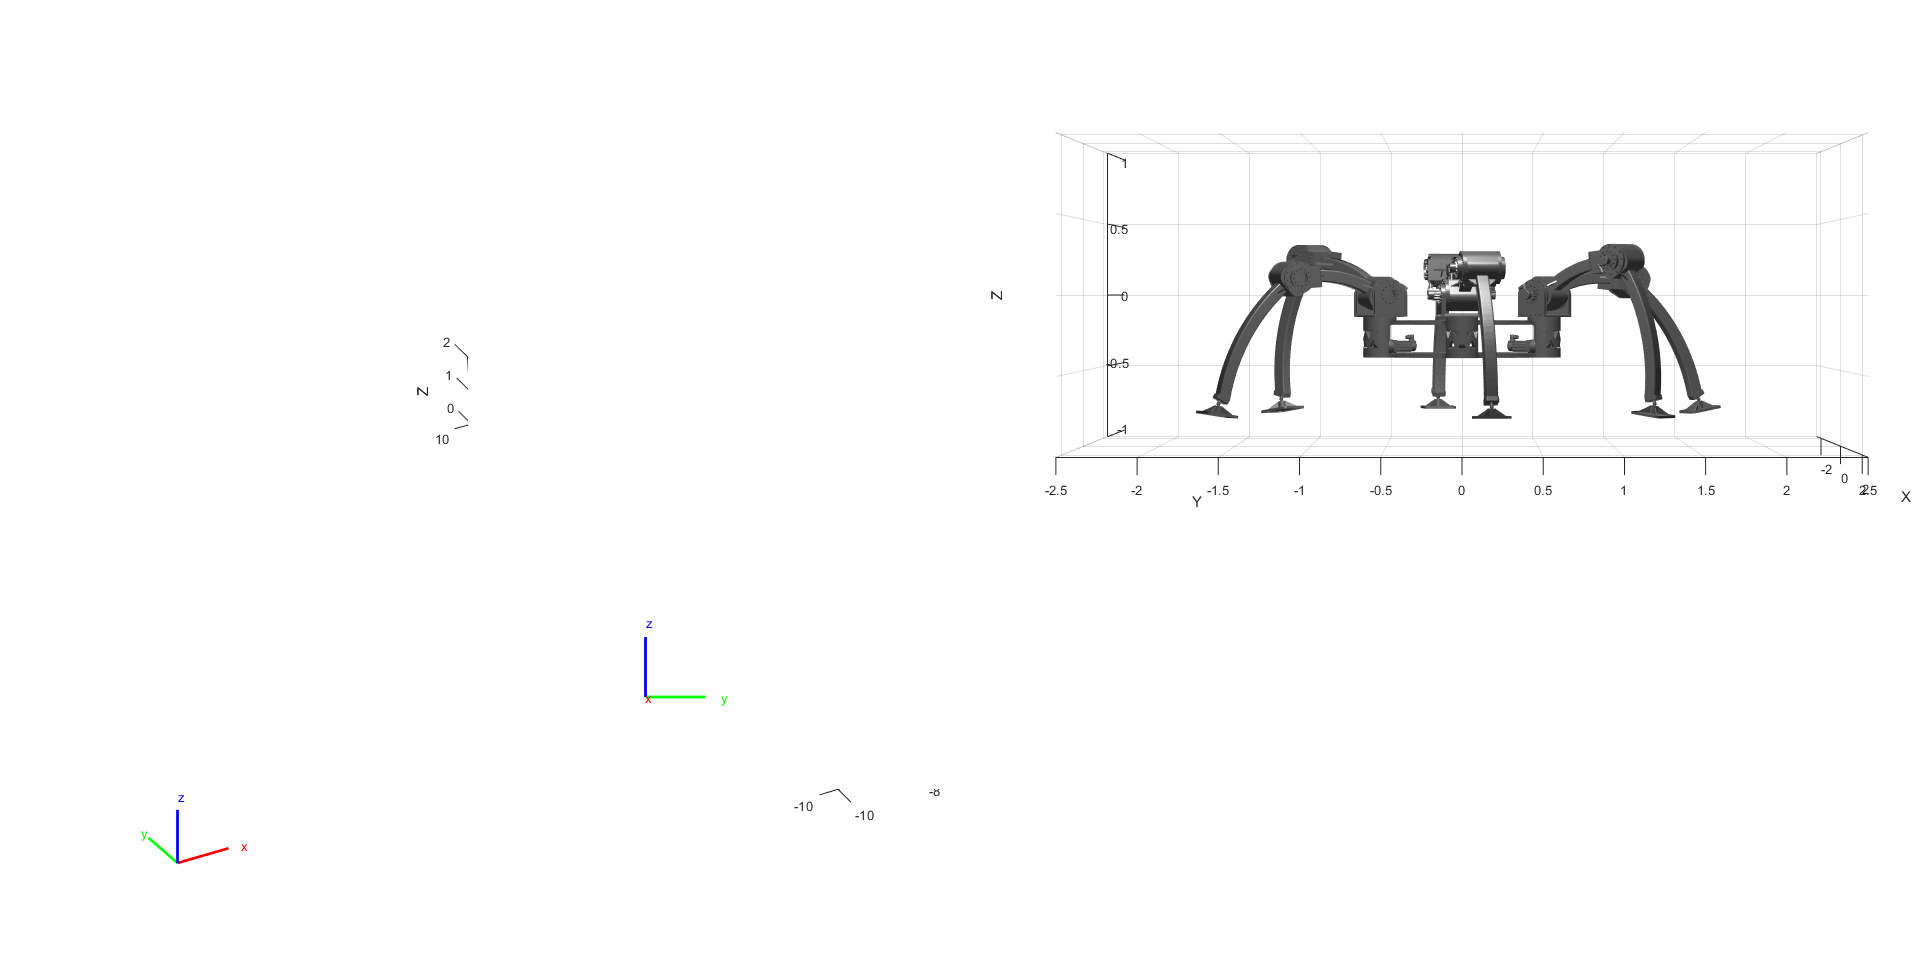

drawnow;
t = toc;
%     disp(datestr(datenum(0,0,0,0,0,t),'HH:MM:SS'))
if make_video
    % Create video of animation
    movie(G);
    movie(H);
    movie(I);
    movie(J);
    % create the video writer
    if climbing_slope
        if strcmpi(slope_type, 'x')
            writerObj_G = VideoWriter('Hexapod Robot Walking Simulation X Slope Test Path - 500mm Pose Height - 40fsp');
            writerObj_H = VideoWriter('Hexapod Robot Walking Simulation X Slope Top View - 500mm Pose Height - 40fsp');
            writerObj_I = VideoWriter('Hexapod Robot Walking Simulation X Slope Front View - 500mm Pose Height - 40fsp');
            writerObj_J = VideoWriter('Hexapod Robot Walking Simulation X Slope Side View - 500mm Pose Height - 40fsp');
        elseif strcmpi(slope_type, 'xy')
            writerObj_G = VideoWriter('Hexapod Robot Walking Simulation XY Slope Test Path - 500mm Pose Height - 40fsp');
            writerObj_H = VideoWriter('Hexapod Robot Walking Simulation XY Slope Top View - 500mm Pose Height - 40fsp');
            writerObj_I = VideoWriter('Hexapod Robot Walking Simulation XY Slope Front View - 500mm Pose Height - 40fsp');
            writerObj_J = VideoWriter('Hexapod Robot Walking Simulation XY Slope Side View - 500mm Pose Height - 40fsp');
        end
    else
        writerObj_G = VideoWriter('Hexapod Robot Walking Simulation Test Path - 700mm Pose Height - 40fsp');
        writerObj_H = VideoWriter('Hexapod Robot Walking Simulation Top View - 700mm Pose Height - 40fsp');
        writerObj_I = VideoWriter('Hexapod Robot Walking Simulation Front View - 700mm Pose Height - 40fsp');
        writerObj_J = VideoWriter('Hexapod Robot Walking Simulation Side View - 700mm Pose Height - 40fsp');
    end
    writerObj_G.FrameRate = 40;
    writerObj_H.FrameRate = 40;
    writerObj_I.FrameRate = 40;
    writerObj_J.FrameRate = 40;
    % set the seconds per image
    % open the video writer
    open(writerObj_G);
    open(writerObj_H);
    open(writerObj_I);
    open(writerObj_J);
    % write the frames to the video
    for i=1:length(G)
        % convert the image to a frame
        frame_G = G(i);
        frame_H = H(i);
        frame_I = I(i);
        frame_J = J(i);
        writeVideo(writerObj_G, frame_G);
        writeVideo(writerObj_H, frame_H);
        writeVideo(writerObj_I, frame_I);
        writeVideo(writerObj_J, frame_J);
    end
    % close the writer object
    close(writerObj_G);
    close(writerObj_H);
    close(writerObj_I);
    close(writerObj_J);
end

function hg_transform = make_transform(pose, world, iteration)
% MAKE_TRANSFORM Builds a homogeneous transformation matrix based on the input data of
% pose, world, and current iteration.
    arguments
        pose (6,:) double {mustBeNumeric, mustBeFinite}
        world (3,:) double {mustBeNumeric, mustBeFinite}
        iteration (1,1) double {mustBeNumeric, mustBeFinite}
    end

    theta_x = 0;
    theta_y = 0;
    theta_z = world(3,iteration) - pi/2; % Angle of rotation relative to Z-Axis of world
    x = world(1,iteration)/1000 + pose(1,iteration)/1000; % X position of robot center
    y = world(2,iteration)/1000 + pose(2,iteration)/1000; % Y position of robot center
    z = pose(3,iteration)/1000 + 0.08; % Z position of robot center
    rot_x = [1, 0, 0, 0;
             0, cos(theta_x), -sin(theta_x), 0;
             0, sin(theta_x), cos(theta_x), 0;
             0, 0, 0, 1]; % Rotation about the X axis
    rot_y = [cos(theta_y), 0, sin(theta_y), 0;
             0, 1, 0, 0;
             -sin(theta_y), 0, cos(theta_y), 0;
             0, 0, 0, 1]; % Rotation about the Y axis
    rot_z = [cos(theta_z), -sin(theta_z), 0, 0;
             sin(theta_z), cos(theta_z), 0, 0;
             0, 0, 1, 0;
             0, 0, 0, 1]; % Rotation about the Z axis
    hg_transform = [cos(theta_z), -sin(theta_z), 0, x;
                    sin(theta_z), cos(theta_z), 0, y;
                    0, 0, 1, z;
                    0, 0, 0, 1]; % Built homogeneous transformation matrix
end

function configuration = current_config(joint_angles, iteration)
% CURRENT_CONFIG parses the desired joint angles for a specified iteration
% and outputs them in the configuration format needed to show the rigid
% body tree model.
    arguments
        joint_angles (3,6,:) double {mustBeNumeric, mustBeFinite}
        iteration (1,1) double {mustBeNumeric, mustBeFinite}
    end
    
    configuration = zeros(1,18);
    joint_1_co_ord = [1,1,1,1,1,1;  1,4,7,10,13,16];
    joint_2_co_ord = [1,1,1,1,1,1;  2,5,8,11,14,17];
    joint_3_co_ord = [1,1,1,1,1,1;  3,6,9,12,15,18];
    % All of joint 1
    configuration(sub2ind(size(configuration),joint_1_co_ord(1,:),joint_1_co_ord(2,:))) = joint_angles(1,:,iteration);
    % All of joint 2
    configuration(sub2ind(size(configuration),joint_2_co_ord(1,:),joint_2_co_ord(2,:))) = joint_angles(2,:,iteration);
    % All of joint 3
    configuration(sub2ind(size(configuration),joint_3_co_ord(1,:),joint_3_co_ord(2,:))) = joint_angles(3,:,iteration);
    % configuration(1,1:3) = 0; % Test code to verify the robot is facing the correct direction. Leg 1 is on the front left side.
end

function r = Rotation(axis, angle)
    if axis == 'x'
        r = [1 0 0;0 cos(angle) -sin(angle);0 sin(angle) cos(angle)];
    elseif axis == 'y'
        r = [cos(angle) 0 sin(angle);0 1 0;-sin(angle) 0 cos(angle)];
    elseif axis == 'z'
        r = [cos(angle) -sin(angle) 0;sin(angle) cos(angle) 0;0 0 1];
    else
        error('Rotation axis is not x, y, or z');
    end
end